close all; clear; clc;
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end
clear list_factory index_interpreter default_name i;



materials = [0.02 0.02 0.03 0.03 0.04 0.05 0.05;
            0.18 0.12 0.10 0.09 0.08 0.07 0.07;
            0.08 0.24 0.57 0.69 0.71 0.73 0.73;
            0.20 0.15 0.10 0.08 0.04 0.02 0.02;
            0.03 0.06 0.39 0.63 0.70 0.73 0.73];

frequencies = [0 125 250 500 1000 2000 4000 8000 16000 22050]

frequencies =            0         125         250         500        1000        2000        4000        8000       16000       22050


inv_materials = 1-materials

inv_materials =     0.9800    0.9800    0.9700    0.9700    0.9600    0.9500    0.9500
    0.8200    0.8800    0.9000    0.9100    0.9200    0.9300    0.9300
    0.9200    0.7600    0.4300    0.3100    0.2900    0.2700    0.2700
    0.8000    0.8500    0.9000    0.9200    0.9600    0.9800    0.9800
    0.9700    0.9400    0.6100    0.3700    0.3000    0.2700    0.2700


materials_db = 20*log10(1-materials)

materials_db =    -0.1755   -0.1755   -0.2646   -0.2646   -0.3546   -0.4455   -0.4455
   -1.7237   -1.1103   -0.9151   -0.8192   -0.7242   -0.6303   -0.6303
   -0.7242   -2.3837   -7.3306  -10.1728  -10.7520  -11.3727  -11.3727
   -1.9382   -1.4116   -0.9151   -0.7242   -0.3546   -0.1755   -0.1755
   -0.2646   -0.5374   -4.2934   -8.6360  -10.4576  -11.3727  -11.3727


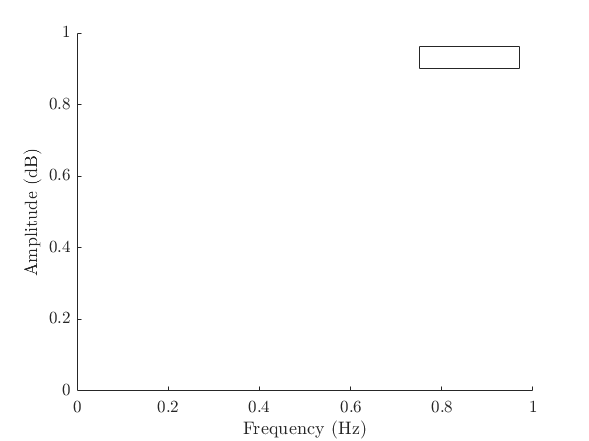

%semilogx(frequencies, materials_db)


% Plot magnitude spectra for each row of materials
xlabel('Frequency (Hz)');
ylabel('Amplitude (dB)');
legend('Material 1', 'Material 2', 'Material 3', 'Material 4', 'Material 5');

materialIndex = 5

materialIndex = 5


mat_curog0 = linspace(materials_db(materialIndex,1), materials_db(materialIndex,1), 5)

mat_curog0 =    -0.2646   -0.2646   -0.2646   -0.2646   -0.2646


mat_cur0 = linspace(materials_db(materialIndex,1), materials_db(materialIndex,2), 10);
mat_cur1 = linspace(materials_db(materialIndex,2), materials_db(materialIndex,3), 20);
mat_cur2 = linspace(materials_db(materialIndex,3), materials_db(materialIndex,4), 40);
mat_cur3 = linspace(materials_db(materialIndex,4),materials_db(materialIndex,5), 80);
mat_cur4 = linspace(materials_db(materialIndex,5),materials_db(materialIndex,6), 160);
mat_cur5 = linspace(materials_db(materialIndex,6), materials_db(materialIndex,7), 320);
mat_cur6 = linspace(materials_db(materialIndex,7), materials_db(materialIndex,7), 640);
mat_cur7 = linspace(materials_db(materialIndex,7), materials_db(materialIndex,7), 882);

figure
totalmatttttttttttt = [mat_curog0 mat_cur0 mat_cur1 mat_cur2 mat_cur3 mat_cur4 mat_cur5 mat_cur6 mat_cur7]

totalmatttttttttttt =    -0.2646   -0.2646   -0.2646   -0.2646   -0.2646   -0.2646   -0.2949   -0.3252   -0.3555   -0.3858   -0.4162   -0.4465   -0.4768   -0.5071   -0.5374   -0.5374   -0.7351   -0.9328   -1.1305   -1.3282   -1.5259   -1.7235   -1.9212   -2.1189   -2.3166   -2.5143   -2.7119   -2.9096   -3.1073   -3.3050   -3.5027   -3.7004   -3.8980   -4.0957   -4.2934   -4.2934   -4.4048   -4.5161   -4.6274   -4.7388   -4.8501   -4.9615   -5.0728   -5.1842   -5.2955   -5.4069   -5.5182   -5.6296   -5.7409   -5.8523


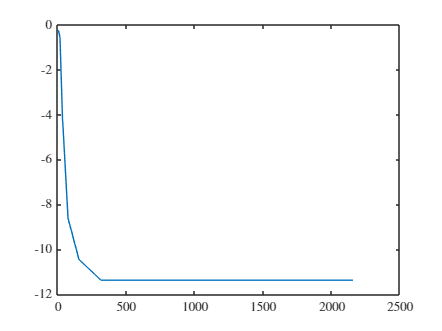

plot(totalmatttttttttttt)


writematrix(totalmatttttttttttt,'tabledata.txt');


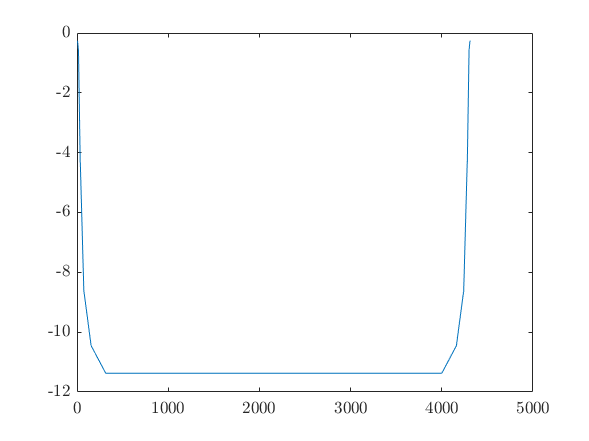

%Doubling the signal

% First we mirror the spectrum around pi -- it must exist from 0 to 2*pi

for i=0:2156
    totalmatttttttttttt(2158+i) = totalmatttttttttttt(2157-i);
end

plot(totalmatttttttttttt)

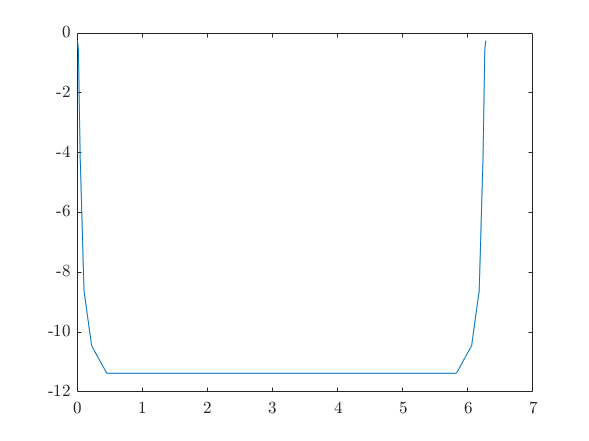

%Normalizing the signal
% Make a frequency scale from 0 to pi
delta_freq = pi/2157;
freq_axis(1)=0;
for i=2:2157
    freq_axis(i) = freq_axis(i-1) + delta_freq;
end

% Make a frequency scale from 0 to 2*pi
delta_freq = (2*pi)/4314;
freq_axis_2pi(1)=0;
for i=2:4314
    freq_axis_2pi(i) = freq_axis_2pi(i-1) + delta_freq;
end

plot(freq_axis_2pi,totalmatttttttttttt)


h_d = real(ifft(totalmatttttttttttt));


%Truncation

M = 200;
h = h_d

h =   -11.0204    0.3495    0.3413    0.3283    0.3113    0.2914    0.2700    0.2481    0.2269    0.2073    0.1898    0.1747    0.1621    0.1516    0.1430    0.1357    0.1292    0.1230    0.1167    0.1103    0.1037    0.0968    0.0899    0.0832    0.0769    0.0713    0.0663    0.0621    0.0586    0.0556    0.0531    0.0509    0.0487    0.0464    0.0440    0.0415    0.0388    0.0361    0.0333    0.0307    0.0281    0.0258    0.0236    0.0216    0.0197    0.0179    0.0161    0.0143    0.0126    0.0109


%h_new = [0];

m_sum = 1:M;


%sys = tf(h(1,1:end),[1],[],'Variable','z^-1');
%figure(1)
%bode(sys)
%ew = @(w) exp(-i*m_sum*w)
%H = @(w) sum(ew(w).*h)

%invfft = fft(h)
%plot(angle(invfft))

%freqz(h,1,M)

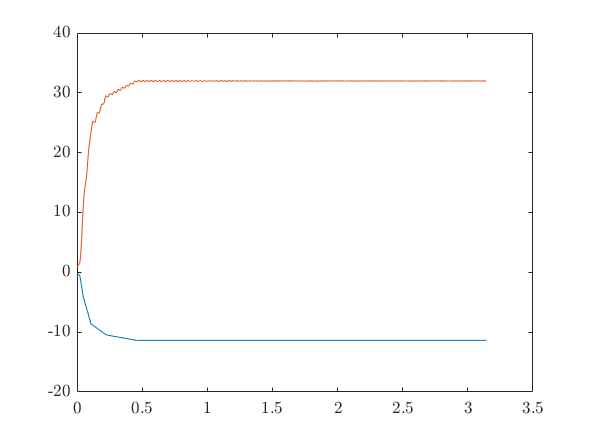

L = 200;

%Create symmetrical
h_sym(1:2157) = h_d(2158:4314);
h_sym(2158:4314) = h_d(1:2157);
for i=-24:24
    stem_axis_h(25+i) = i-1;
end

% Next, calculate the autocorrelation of the impulse response -- using all
% 2048 impulse response samples. Applying the xcorr M-function creates 4095
% autocorrelation coefficients.
r_h = xcorr(h_sym);
for i=-20:20
    stem_axis_r_h(21+i) = 4314+i;
end
%stem(stem_axis_r_h, r_h(2028:2068))

% Based on the autocorr.-coefficients, the autocorr.-matrix and vector are
% next generatd
R_h = toeplitz(r_h(4314:4314+L-1));
b_h = r_h(4315:4315+L-1);

% Solving the equation system provides L samples of the impulse response
% from the High-Order AR model of the desired filter. This impulse response
% is next considered as the observable signal.
a_h = -inv(R_h)*b_h';
%plot([1 a_h(1:50)'])

% Using now the inpulse response as the observable signal, we now calculate
% M MA filter coefficients using the usual autocorrelation method. Remember
% that the first sample in the impulse response equals 1 (the coefficient
% a_0).
r_a = xcorr([1 a_h']');

% As usual, the autocorr. matrix and vector are created based on the
% autocorrelation coefficients.
R_a = toeplitz(r_a(L+1:L+M));
b_a = r_a(L+2:L+M+1);

% Solving the equation system provides the L MA coefficients
a_a = -inv(R_a)*b_a;

% Now we need to calculate the gain factor for 0dB DC gain
G_a = 1;
for i=1:M
    G_a = G_a + a_a(i);
end
G_a = 1/G_a;

% ...and the finally, calculate and plot the approximated MA and the
% desired amplitude spectrum
[H_a,w] = freqz([1 a_a'],1, 2157);
plot(freq_axis, totalmatttttttttttt(1:2157), freq_axis, G_a*abs(H_a));

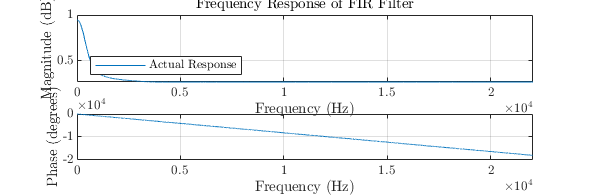

% Define the filter specifications
Fs = 44100; % specify the sampling frequency (in Hz)
normalized_freq = frequencies / (Fs/2); % normalize the frequencies
attenuations = inv_materials(5,:); % specify the desired attenuation values at the corresponding frequencies
delta_f = 1; % specify the frequency resolution of the filter (in Hz)

N=200;

% Compute the frequency response of the filter
f = 0:delta_f:Fs/2; % create a frequency vector from 0 to the Nyquist frequency
H_desired = interp1(frequencies, 10.^(attenuations/20), f, 'pchip', 'extrap'); % compute the desired frequency response using interpolation
w = (2*pi*f/Fs); % convert the frequency vector to radians/sample
w = w/w(end);
h_hamming = fir2(N, w, H_desired, hamming(N+1)); % design the filter using the Parks-McClellan algorithm
h_hann = fir2(N, w, H_desired, hann(N+1)); % design the filter using the Parks-McClellan algorithm
h_blackmann = fir2(N, w, H_desired, blackman(N+1)); % design the filter using the Parks-McClellan algorithm
h_rect = fir2(N, w, H_desired, rectwin(N+1)); % design the filter using the Parks-McClellan algorithm

% Apply the filter to a signal (for example)
x = randn(1, 1000); % create a random signal
y = filter(h, 1, x); % apply the filter to the signal

% Plot the frequency response of the filter
figure('Position', [10 10 900 300]);
hold on
freqz(h_hamming, 1, f, Fs); % compute the actual frequency response of the filter

H_actual_hann = freqz(h_hann, 1, f, Fs); % compute the actual frequency response of the filter
H_actual_blackmann = freqz(h_blackmann, 1, f, Fs); % compute the actual frequency response of the filter
H_actual_rect = freqz(h_rect, 1, f, Fs); % compute the actual frequency response of the filter
%semilogx(f, 20*log10(abs(H_actual_hamming)), 'b', frequencies, attenuations, 'ro', 'LineWidth', 2);
hold off
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Frequency Response of FIR Filter');
legend('Actual Response', 'Desired Points', 'Location', 'southwest');

%Minimum phase
h_phase = firminphase(abs(h_hamming))

h_phase =     1.0169    0.0024    0.0023    0.0022    0.0021    0.0020    0.0019    0.0018    0.0017    0.0016    0.0015    0.0014    0.0013    0.0012    0.0012    0.0011    0.0011    0.0010    0.0009    0.0009    0.0008    0.0008    0.0007    0.0007    0.0006    0.0006    0.0005    0.0005    0.0005    0.0004    0.0004    0.0004    0.0003    0.0003    0.0003    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000


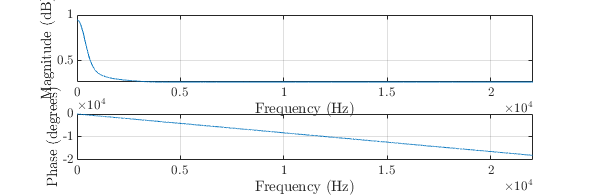

freqz(h_hamming, 1, f, Fs); % compute the actual frequency response of the filter

%%%Composite Transmission Loss

%Surfaces
floorSurface = 7.790*4.130;
RugSurface = 2.60*4.0;
sideWallsSurface = 2.130*7.790;
endWallsSurface = 4.130*2.130;

BigTile = 1.81*0.60;
MediumTile = 0.60*1.20;
smallTile = 0.90*0.60;

materials = [0.02 0.02 0.03 0.03 0.04 0.05 0.05;
            0.18 0.12 0.10 0.09 0.08 0.07 0.07;
            0.08 0.24 0.57 0.69 0.71 0.73 0.73;
            0.20 0.15 0.10 0.08 0.04 0.02 0.02;
            0.03 0.06 0.39 0.63 0.70 0.73 0.73;
            0.41 0.67 0.58 0.59 0.68 0.35 0.35]

materials =     0.0200    0.0200    0.0300    0.0300    0.0400    0.0500    0.0500
    0.1800    0.1200    0.1000    0.0900    0.0800    0.0700    0.0700
    0.0800    0.2400    0.5700    0.6900    0.7100    0.7300    0.7300
    0.2000    0.1500    0.1000    0.0800    0.0400    0.0200    0.0200
    0.0300    0.0600    0.3900    0.6300    0.7000    0.7300    0.7300
    0.4100    0.6700    0.5800    0.5900    0.6800    0.3500    0.3500


controllWall = ((endWallsSurface - (2*BigTile) - smallTile) * materials(1,:) + (2*BigTile + smallTile) * materials(6,:))/endWallsSurface

controllWall =     0.1402    0.2204    0.1996    0.2026    0.2373    0.1425    0.1425


doorWall = (((sideWallsSurface - (4*BigTile) + smallTile) * materials(1,:) + (smallTile + (4*BigTile) * materials(6,:))))/sideWallsSurface

doorWall =     0.1553    0.2234    0.2075    0.2101    0.2414    0.1627    0.1627


OuterWall = (((sideWallsSurface - (3*BigTile) + (3*MediumTile)) * materials(1,:) + ((3*BigTile) + (3*MediumTile))*materials(6,:)))/sideWallsSurface

OuterWall =     0.1526    0.2375    0.2174    0.2207    0.2594    0.1610    0.1610


floor = ((floorSurface-RugSurface) * materials(2,:) + RugSurface*materials(3,:))/floorSurface

floor =     0.1477    0.1588    0.2519    0.2840    0.2837    0.2833    0.2833


newMats = [controllWall;
           doorWall;
           OuterWall;
           floor;
           materials(4,:)
           materials(6,:)]

newMats =     0.1402    0.2204    0.1996    0.2026    0.2373    0.1425    0.1425
    0.1553    0.2234    0.2075    0.2101    0.2414    0.1627    0.1627
    0.1526    0.2375    0.2174    0.2207    0.2594    0.1610    0.1610
    0.1477    0.1588    0.2519    0.2840    0.2837    0.2833    0.2833
    0.2000    0.1500    0.1000    0.0800    0.0400    0.0200    0.0200
    0.4100    0.6700    0.5800    0.5900    0.6800    0.3500    0.3500


inv_newMats = 1 - newMats

inv_newMats =     0.8598    0.7796    0.8004    0.7974    0.7627    0.8575    0.8575
    0.8447    0.7766    0.7925    0.7899    0.7586    0.8373    0.8373
    0.8474    0.7625    0.7826    0.7793    0.7406    0.8390    0.8390
    0.8523    0.8412    0.7481    0.7160    0.7163    0.7167    0.7167
    0.8000    0.8500    0.9000    0.9200    0.9600    0.9800    0.9800
    0.5900    0.3300    0.4200    0.4100    0.3200    0.6500    0.6500


% Define the filter specifications
Fs = 44100; % specify the sampling frequency (in Hz)
normalized_freq = frequencies / (Fs/2); % normalize the frequencies
delta_f = 1; % specify the frequency resolution of the filter (in Hz)
N=200;
% Compute the frequency response of the filter
f = 0:delta_f:Fs/2; % create a frequency vector from 0 to the Nyquist frequency



%All desired frequency response
%H_desired_controllWall = interp1(frequencies, 10.^(inv_newMats(1,:)/20), f, 'pchip', 'extrap'); % compute the desired frequency response using interpolation
%H_desired_doorWall = interp1(frequencies, 10.^(inv_newMats(2,:)/20), f, 'pchip', 'extrap'); % compute the desired frequency response using interpolation
%H_desired_outerWall = interp1(frequencies, 10.^(inv_newMats(3,:)/20), f, 'pchip', 'extrap'); % compute the desired frequency response using interpolation
%H_desired_floor = interp1(frequencies, 10.^(inv_newMats(4,:)/20), f, 'pchip', 'extrap'); % compute the desired frequency response using interpolation
%H_desired_ceiling = interp1(frequencies, 10.^(inv_newMats(5,:)/20), f, 'pchip', 'extrap'); % compute the desired frequency response using interpolation
%H_desired_endWall_cloth = interp1(frequencies, 10.^(inv_newMats(6,:)/20), f, 'pchip', 'extrap'); % compute the desired frequency response using interpolation 

freq_normal = frequencies/(Fs/2)

freq_normal =          0    0.0057    0.0113    0.0227    0.0454    0.0907    0.1814    0.3628    0.7256    1.0000


x = [0.1402 controllWall 0.1425 0.1425]

x =     0.1402    0.1402    0.2204    0.1996    0.2026    0.2373    0.1425    0.1425    0.1425    0.1425



test = fir2(N, freq_normal, x)

test =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002


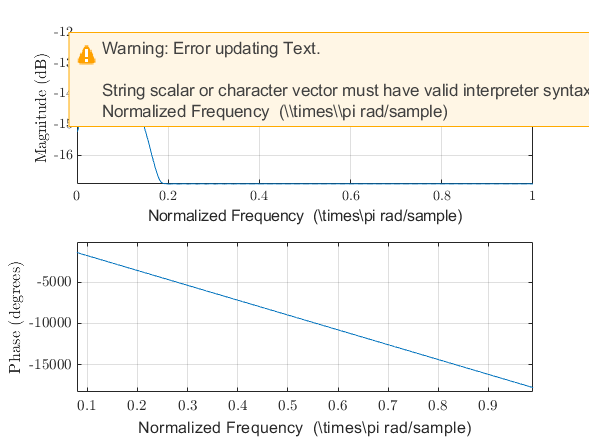

freqz(test, 1, Fs); 